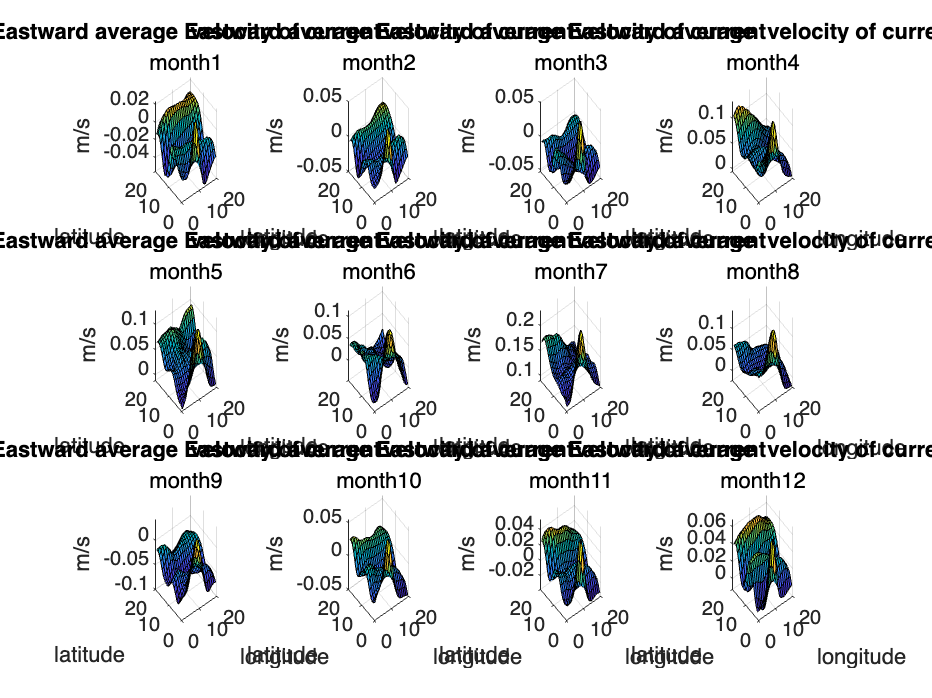

[a1,b1,c1]=size(AE);%East current velocity
[a2,b2,c2]=size(BN);%North current velocity
[a3,b3,c3]=size(EN);%Compound current velocity

A=zeros(12*a1,b1);
B=zeros(12*a2,b2);
C=zeros(12*a3,b3);
for i=1:12:c1
    %every month
    M1=[squeeze(AE(:,:,i));
        squeeze(AE(:,:,i+1));
        squeeze(AE(:,:,i+2));
        squeeze(AE(:,:,i+3));
        squeeze(AE(:,:,i+4));
        squeeze(AE(:,:,i+5));
        squeeze(AE(:,:,i+6));
        squeeze(AE(:,:,i+7));
        squeeze(AE(:,:,i+8));
        squeeze(AE(:,:,i+9));
        squeeze(AE(:,:,i+10));
        squeeze(AE(:,:,i+11)) ];
    M2=[squeeze(BN(:,:,i));
        squeeze(BN(:,:,i+1));
        squeeze(BN(:,:,i+2));
        squeeze(BN(:,:,i+3));
        squeeze(BN(:,:,i+4));
        squeeze(BN(:,:,i+5));
        squeeze(BN(:,:,i+6));
        squeeze(BN(:,:,i+7));
        squeeze(BN(:,:,i+8));
        squeeze(BN(:,:,i+9));
        squeeze(BN(:,:,i+10));
        squeeze(BN(:,:,i+11)) ]; 
    M3=[squeeze(EN(:,:,i));
        squeeze(EN(:,:,i+1));
        squeeze(EN(:,:,i+2));
        squeeze(EN(:,:,i+3));
        squeeze(EN(:,:,i+4));
        squeeze(EN(:,:,i+5));
        squeeze(EN(:,:,i+6));
        squeeze(EN(:,:,i+7));
        squeeze(EN(:,:,i+8));
        squeeze(EN(:,:,i+9));
        squeeze(EN(:,:,i+10));
        squeeze(EN(:,:,i+11)) ]; 
    A=M1./(c1/12)+A; % every month average value E
    B=M2./(c1/12)+B; % every month average value N
    C=M3./(c1/12)+C; % every month average value M
end

figure()
for k3=1:a1:12*a1    
    k4=round(k3/a1)+1;
    subplot(3,4,k4)
    surf(A(k3:a1+k3-1,:));    %作图
    title("Eastward average  velocity of current",['month',num2str(k4)])
    xlabel("longitude");
    ylabel("latitude");
    zlabel("m/s")    
end

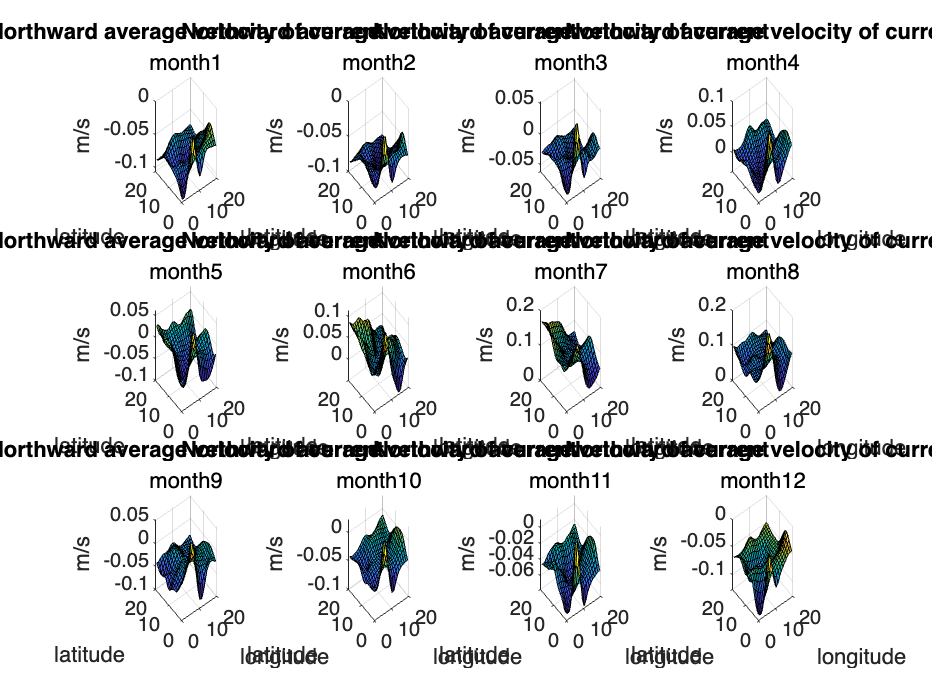


figure()
for k3=1:a1:12*a1    
    k4=round(k3/a1)+1;
    subplot(3,4,k4)
    surf(B(k3:a1+k3-1,:));    %作图
    title("Northward average velocity of current",['month',num2str(k4)])
    xlabel("longitude");
    ylabel("latitude");
    zlabel("m/s")
end

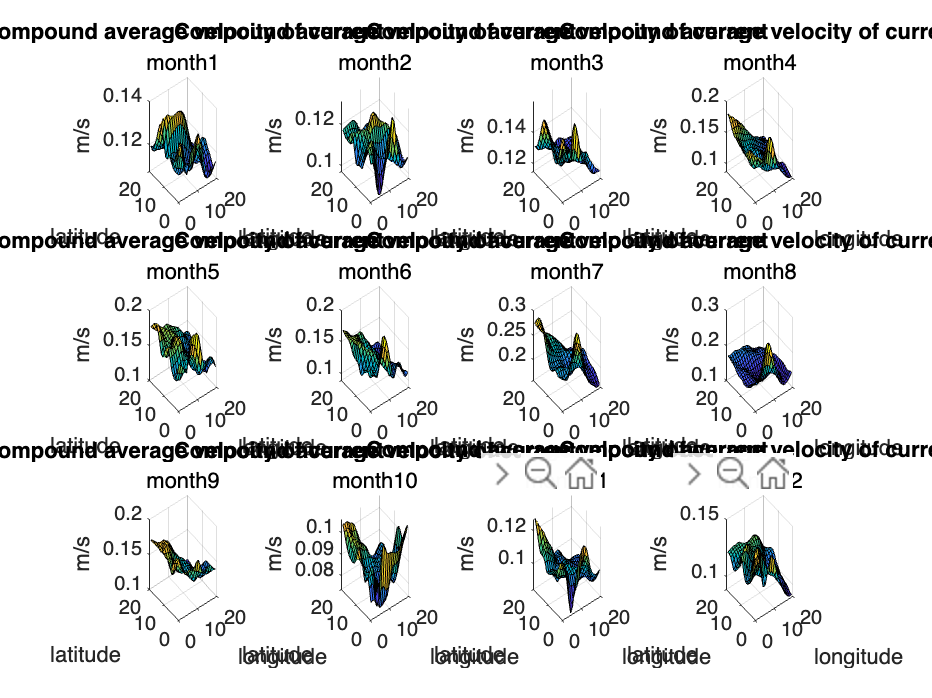


figure()
for k3=1:a1:12*a1    
    k4=round(k3/a1)+1;
    subplot(3,4,k4)
    surf(C(k3:a1+k3-1,:));    %作图
    title("Compound average velocity of current",['month',num2str(k4)])
    xlabel("longitude");
    ylabel("latitude");
    zlabel("m/s")
end


% out=VideoWriter('current_velocity_month_EN.avi');
% out.FrameRate=5;
% open(out);
% for k1=1:c1
%     figure(k1)
%     subplot(211)
%     surf(AE(:,:,k1));    %作图
%     legend(['month',num2str(k1)]);
%     title("Eastward velocity of current")
%     xlabel("longitude");ylabel("latitude");zlabel("m/s")
%     subplot(212)
%     surf(BN(:,:,k1));    %作图
%     legend(['month',num2str(k1)]);
%     title("Northward velocity of current")
%     xlabel("longitude");ylabel("latitude");zlabel("m/s")
%     hold on
%     F=getframe(gcf);
%     writeVideo(out,F);
%     close(gcf);%此处语句不可省，降低内存占用
% end
% hold off
% close(out);

% % colorbar
% % figure()
% % surf(A)
% % colormap summer
% % for i = 1:a
% %     for j = 1:b
% %         text(i, j, sprintf('%d',A(i,j)))
% %     end
% % end

% out=VideoWriter('Eastword and Northword Average current velocity monthly.avi');
% out.FrameRate=5;
% open(out);
% for k3=1:a1:12*a1
%     figure(k3)
%     k4=round(k3/a1)+1;
%     subplot(211)
%     surf(A(k3:a1+k3-1,:));    %作图
%     legend(['month',num2str(k4)]);
%     title("Average Eastward velocity of current")
%     xlabel("longitude");ylabel("latitude");zlabel("m/s")    
%     subplot(212)
%     surf(B(k3:a1+k3-1,:));    %作图
%     legend(['month',num2str(k4)]);
%     title("Average Northward velocity of current")
%     xlabel("longitude");ylabel("latitude");zlabel("m/s")
%     hold on
%     F=getframe(gcf);
%     writeVideo(out,F);
%     close(gcf);%此处语句不可省，降低内存占用
% end
% hold off
% close(out);
